%A1 = 100; %Amplitude
%w1 = 2*pi*800; %angular frequency 
%p1 = -1*pi/3; %phase shift
%fsamp = 11025; %sampling frequency
%Tsamp = 1/fsamp; %sampling period

%A2 = 80; %Amplitude
%w2 = 2*pi*1200; %angular frequency 
%p2 = pi/4; %phase shift

%tt = (0: Tsamp: .5); %time vector for the conversion of a continuous-time sinusoid to a discrete-time sinusoid

%x1 = A1*cos(w1*tt + p1);
%soundsc(x1, fsamp);

%x2 = A2*cos(w2*tt + p2);
%soundsc(x1, fsamp); %This is louder than sound a

%tt_pause = (0: Tsamp: .1);
%sz = numel(tt_pause); %1103 samples = .1 second

%xx = [x1, zeros(1, sz), x2];
%soundsc(xx, fsamp);

%tt_plot = Tsamp*(1:length(xx)); %time vector of 1.1 seconds
%plot(tt_plot, xx);
%soundsc(xx, 2*fsamp); %the higher frequency causes the duration to decrease and the pitch to increase. soundsc(y,Fs) sends audio signal y to the speaker at sample rate Fs. the duration is halved.

% x.Amp = 7;
% x.phase = -pi/2;
% x.freq = 100;
% x.fs = 11025
% x.timeInterval = 0:(1/x.fs):0.05;
% x.values = x.Amp*cos(2*pi*(x.freq)*(x.timeInterval) + x.phase);
% x.name = 'My Signal';
% x; %---- echo the contents of the structure "x"
% plot( x.timeInterval, x.values )
% title( x.name )

key2note(1, 40, .125)

freq = 261.6256

ans =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210



%--- play_scale.m
%---
scale.keys = [40 42 44 45 47 49 51 52]

scale = struct with fields:
    keys: [40 42 44 45 47 49 51 52]


numel(scale.keys)

ans = 8

%--- NOTES: C D E F G A B C
% key #40 is middle-C
%
scale.durations = 0.25 * ones(1,length(scale.keys))

scale = struct with fields:
         keys: [40 42 44 45 47 49 51 52]
    durations: [0.2500 0.2500 0.2500 0.2500 0.2500 0.2500 0.2500 0.2500]


numel(scale.durations)

ans = 8

fs = 11025; %-- or 8000 Hz
xx = zeros(1, sum(scale.durations)*fs+length(scale.keys)) %sum(A) returns the sum of the elements of A along the first array dimension whose size does not equal 1.

xx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


n1 = 1

n1 = 1

for kk = 1:length(scale.keys)
    keynum = scale.keys(kk)
    tone = key2note(1, keynum, scale.durations)
    n2 = n1 + length(tone) - 1 %for placing a key lengthed signal/vector into the 8-key sized vector xx
    xx(n1:n2) = xx(n1:n2) + tone %<=== Insert the note
    n1 = n2 + 1;
end

keynum = 40

freq = 261.6256

tone =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


n2 = 2757

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


keynum = 42

freq = 293.6648

tone =     1.0000    0.9860    0.9445    0.8766    0.7842    0.6698    0.5368    0.3887    0.2298    0.0645   -0.1026   -0.2669   -0.4237   -0.5687   -0.6977   -0.8073   -0.8943   -0.9564   -0.9917   -0.9993   -0.9789   -0.9312   -0.8575   -0.7599   -0.6410   -0.5041   -0.3532   -0.1924   -0.0263    0.1406    0.3036    0.4580    0.5997    0.7246    0.8293    0.9108    0.9668    0.9959    0.9971    0.9704    0.9166    0.8372    0.7344    0.6111    0.4707    0.3172    0.1548   -0.0120   -0.1784   -0.3398


n2 = 5514

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


keynum = 44

freq = 329.6276

tone =     1.0000    0.9824    0.9302    0.8454    0.7307    0.5904    0.4292    0.2530    0.0679   -0.1196   -0.3029   -0.4756   -0.6315   -0.7652   -0.8720   -0.9480   -0.9908   -0.9987   -0.9714   -0.9099   -0.8165   -0.6943   -0.5477   -0.3818   -0.2024   -0.0160    0.1710    0.3520    0.5206    0.6709    0.7976    0.8962    0.9633    0.9965    0.9946    0.9577    0.8872    0.7854    0.6560    0.5035    0.3332    0.1513   -0.0360   -0.2220   -0.4001   -0.5643   -0.7085   -0.8278   -0.9180   -0.9759


n2 = 8271

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


keynum = 45

freq = 349.2282

tone =     1.0000    0.9803    0.9218    0.8270    0.6995    0.5444    0.3678    0.1767   -0.0214   -0.2187   -0.4073   -0.5798   -0.7295   -0.8503   -0.9376   -0.9878   -0.9991   -0.9709   -0.9044   -0.8022   -0.6683   -0.5080   -0.3276   -0.1344    0.0642    0.2602    0.4460    0.6142    0.7581    0.8721    0.9516    0.9936    0.9963    0.9598    0.8853    0.7758    0.6358    0.4706    0.2869    0.0918   -0.1069   -0.3013   -0.4839   -0.6474   -0.7853   -0.8922   -0.9639   -0.9975   -0.9918   -0.9468


n2 = 11028

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


keynum = 47

freq = 391.9954

tone =     1.0000    0.9751    0.9018    0.7837    0.6266    0.4384    0.2284    0.0070   -0.2147   -0.4258   -0.6156   -0.7749   -0.8957   -0.9720   -0.9999   -0.9782   -0.9078   -0.7923   -0.6375   -0.4509   -0.2420   -0.0210    0.2010    0.4130    0.6045    0.7660    0.8894    0.9686    0.9996    0.9810    0.9136    0.8008    0.6482    0.4634    0.2555    0.0350   -0.1873   -0.4003   -0.5933   -0.7569   -0.8829   -0.9650   -0.9991   -0.9836   -0.9192   -0.8091   -0.6588   -0.4757   -0.2690   -0.0490


n2 = 13785

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


keynum = 49

freq = 440

tone =     1.0000    0.9687    0.8769    0.7301    0.5378    0.3117    0.0662   -0.1835   -0.4216   -0.6335   -0.8057   -0.9275   -0.9912   -0.9930   -0.9327   -0.8140   -0.6444   -0.4345   -0.1974    0.0520    0.2982    0.5257    0.7203    0.8699    0.9651    0.9999    0.9722    0.8836    0.7398    0.5497    0.3252    0.0804   -0.1694   -0.4087   -0.6224   -0.7971   -0.9220   -0.9893   -0.9946   -0.9377   -0.8222   -0.6553   -0.4473   -0.2114    0.0377    0.2845    0.5135    0.7104    0.8628    0.9613


n2 = 16542

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


keynum = 51

freq = 493.8833

tone =     1.0000    0.9606    0.8457    0.6642    0.4304    0.1627   -0.1177   -0.3889   -0.6295   -0.8206   -0.9470   -0.9990   -0.9723   -0.8691   -0.6975   -0.4710   -0.2074    0.0725    0.3466    0.5935    0.7937    0.9315    0.9959    0.9819    0.8907    0.7293    0.5106    0.2517   -0.0271   -0.3037   -0.5564   -0.7653   -0.9140   -0.9907   -0.9895   -0.9104   -0.7597   -0.5491   -0.2954   -0.0184    0.2600    0.5180    0.7352    0.8946    0.9835    0.9950    0.9283    0.7884    0.5866    0.3385


n2 = 19299

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


keynum = 52

freq = 523.2511

tone =     1.0000    0.9559    0.8274    0.6258    0.3690    0.0797   -0.2167   -0.4939   -0.7276   -0.8970   -0.9873   -0.9904   -0.9061   -0.7418   -0.5120   -0.2371    0.0588    0.3495    0.6094    0.8154    0.9495    0.9998    0.9618    0.8389    0.6420    0.3884    0.1005   -0.1962   -0.4756   -0.7131   -0.8876   -0.9838   -0.9931   -0.9147   -0.7557   -0.5299   -0.2574    0.0379    0.3298    0.5926    0.8031    0.9427    0.9991    0.9673    0.8501    0.6579    0.4076    0.1213   -0.1756   -0.4571


n2 = 22056

xx =     1.0000    0.9889    0.9559    0.9016    0.8274    0.7347    0.6258    0.5030    0.3690    0.2269    0.0797   -0.0693   -0.2167   -0.3593   -0.4939   -0.6176   -0.7276   -0.8214   -0.8970   -0.9527   -0.9873   -0.9999   -0.9904   -0.9589   -0.9061   -0.8332   -0.7418   -0.6340   -0.5120   -0.3788   -0.2371   -0.0901    0.0588    0.2065    0.3495    0.4848    0.6094    0.7204    0.8154    0.8924    0.9495    0.9856    0.9998    0.9918    0.9618    0.9105    0.8389    0.7488    0.6420    0.5210


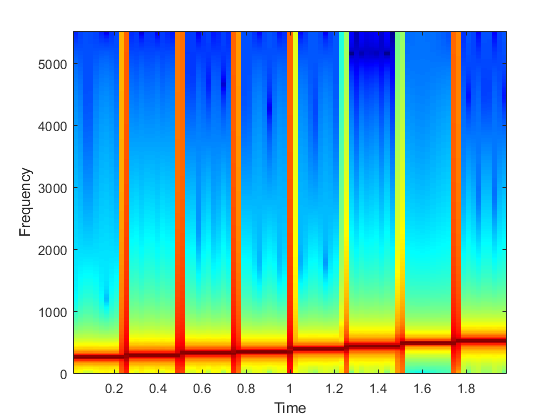

soundsc(xx, fs)
specgram(xx,512,fs)


bpm = 120

bpm = 120

beats_per_second = bpm/60

beats_per_second = 2

seconds_per_beat = 1/beats_per_second

seconds_per_beat = 0.5000

seconds_per_pulse = seconds_per_beat / 4

seconds_per_pulse = 0.1250

theVoices

Unrecognized function or variable 'theVoices'.

%soundsc(theVoices, fs)
%specgram(theVoices,512,fs)

function xx = key2note(X, keynum, dur)
% KEY2NOTE Produce a sinusoidal waveform corresponding to a
% given piano key number
%
% usage: xx = key2note (X, keynum, dur)
%
% xx = the output sinusoidal waveform
% X = complex amplitude for the sinusoid, X = A*exp(j*phi).
% keynum = the piano keyboard number of the desired note
% dur = the duration (in seconds) of the output note
%

fs = 11025; %-- or use 8000 Hz
scale = keynum - 49;
tt = 0:(1/fs):dur;
freq = 440 * ((2^(1/12))^scale)
xx = real( X*exp(j*2*pi*freq*tt) );
end